# **Analysis 1 C161: Live cell analysis V35 NR46 w/ CDC45**

MCF10A geminin venus cells w/ pCW46 (ND-Cdt1-mcherry)

**Testing for:**

Changes in APC inactivation with inhibitor construct/ inhibitors

## **Load Data**

cd('F:\Data\C-Cdt1\C163-live\Plot');
dataDir = 'F:\Data\C-Cdt1\C163-live\Data\';
%imagePath = 'F:\Data\C103-IF\Raw\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    '48 siCtrl dox-',3,11,1:4,[0 0 0],'NR48','Dox-','siCtrl'; %1
    '48 siCtrl dox+',3,2:10,1:4,[0 0 0],'NR48','Dox+','siCtrl'; %1
    
    '48 siGMNN dox-',4,11,1:4,[0 0 0],'NR48','Dox-','siGMNN'; %1
    '48 siGMNN dox+',4,2:10,1:4,[0 0 0],'NR48','Dox+','siGMNN'; %1
    
    '60 siGMNN dox-',5,11,1:4,[0 0 0],'NR60','Dox-','siGMNN'; %1
    '60 siGMNN dox+',5,2:10,1:4,[0 0 0],'NR60','Dox+','siGMNN'; %1
    
    '61 siGMNN dox-',6,11,1:4,[0 0 0],'NR61','Dox-','siGMNN'; %1
    '61 siGMNN dox+',6,2:10,1:4,[0 0 0],'NR61','Dox+','siGMNN'; %1
    
    '62 siGMNN dox-',7,11,1:4,[0 0 0],'NR62','Dox-','siGMNN'; %1
    '62 siGMNN dox+',7,2:10,1:4,[0 0 0],'NR62','Dox+','siGMNN'; %1
    };


%load([dataDir 'sensordata.mat'],'S');
S = loadData_C163(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 72;
frameEdU = 0;
timeStart = 2.1;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

## **View  tr****aces**** to check properties**

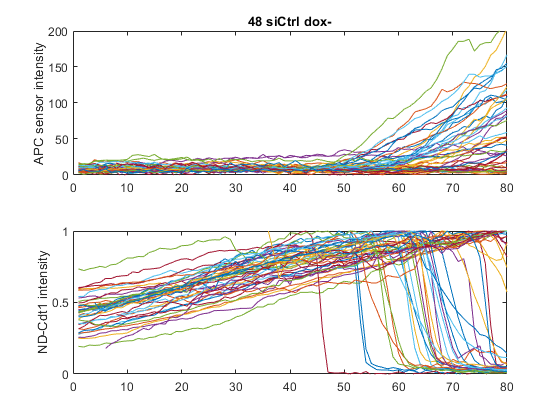

conds = [1];
for i=1:length(conds)
inds = ones(size(S(conds(i)).area(:,end))) ;
cells = find(inds);
nums = randsample(cells,50);
figure,
subplot(2,1,1), plot(S(conds(i)).apcNuc(nums,:)')
ylabel('APC sensor intensity')
ylim([0 200])
title(conditions(conds(i),1));
subplot(2,1,2), plot((S(conds(i)).crlAreaNorm(nums,:))')
ylabel('ND-Cdt1 intensity')
ylim([0 1])
end

## **Plot traces APC aligned **

To check call

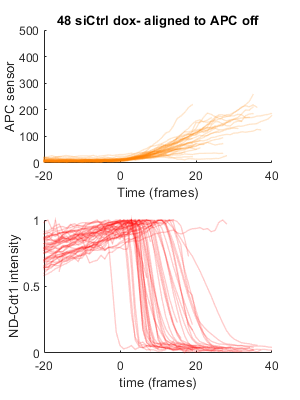

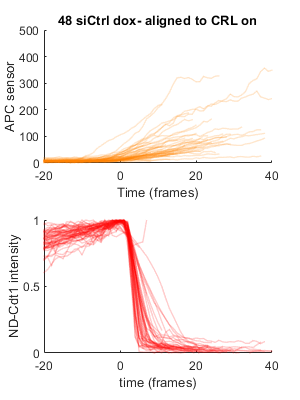

conds=[1];
poiAlign = [2 3];
alignNames = {'APC off','CRL on'};
for p = 1:length(poiAlign)
    figure('pos',[10 10 length(conds)*300 400 ]),
    for i=1:length(conds)
        inds =ones(size(S(conds(i)).area(:,end)))  ;
        cells = find(inds);
        for numcell = randsample(cells,min([100 length(cells)]))'
            timeAligned = xFrames-S(conds(i)).POI(numcell,poiAlign(p));
            subplot(2,length(conds),i),hold on
            patchline(timeAligned,S(conds(i)).apcNuc(numcell,:),...
                'edgecolor',[1 0.5 0],'linewidth',1,'edgealpha',0.2);
            title([conditions{conds(i),1} ' aligned to ' alignNames{(p)}]);
            ylabel('APC sensor');
            ylim([0 500]);
            xlim([-20 40]);
            xlabel('Time (frames)');
            subplot(2,length(conds),i+length(conds)),hold on
            patchline(timeAligned,S(conds(i)).crlAreaNorm(numcell,:),...
                'edgecolor','r','linewidth',1,'edgealpha',0.2);
            ylabel('ND-Cdt1 intensity');
            xlabel('time (frames)');
            ylim([0 1]);
            xlim([-20 40]);
        end
    end
end

Alignment looks good

## Percent inactive APC

Check inhibitors, no accounting for folding time

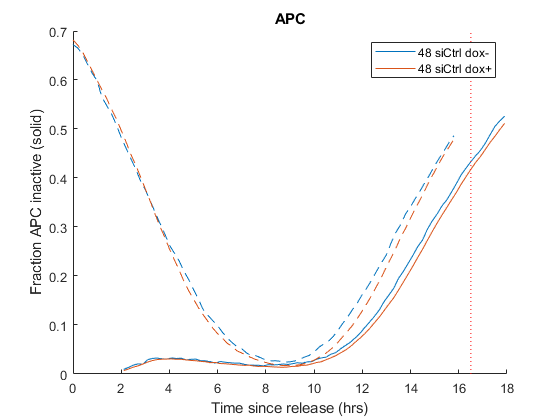

figure, hold on
conds=[1 2];
h = [];
for i=1:length(conds)
    condition = conds(i);
    y1 = S(condition).apcNuc;
    y2 = S(condition).crlNorm;

    percgem=sum(y1>20)./sum(~isnan(y1));
    percCRL=sum(y2<.5)./sum(~isnan(y2));
    h(i) = plot(xTime + timeStart,percgem);
    ax = gca;
    ax.ColorOrderIndex = ax.ColorOrderIndex - 1;
    plot(xTime,percCRL,'--');
end
vline(frameDrugAdded/framesPerHr + timeStart)
%xlim([0 21]);
title('APC');ylabel('Fraction APC inactive (solid)');xlabel('Time since release (hrs)');
hold off
legend(h,conditions(conds,1));

Inhibitors don't seem to impact release of cells, lowish release (around 1/4 of cells, but could be cells losing sensor)

**Plot Cdt1 histograms to look at induction for mCherry**

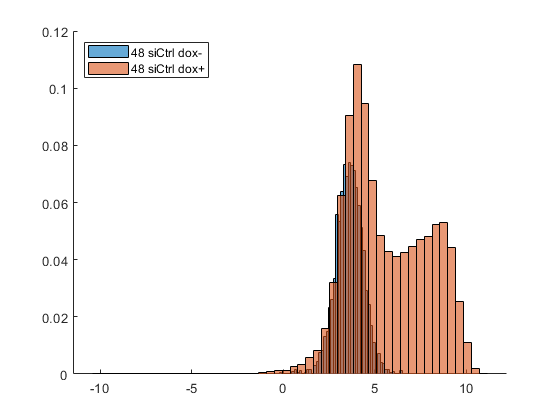

conds=[1 2];

figure, hold on
for i=1:length(conds)
    condition = conds(i);
    histogram(real(log2(S(condition).YFP1(:,end))),50,'Normalization','Probability');
end
legend(conditions(conds,1),'Location','northwest')

**Single traces APC/sig**

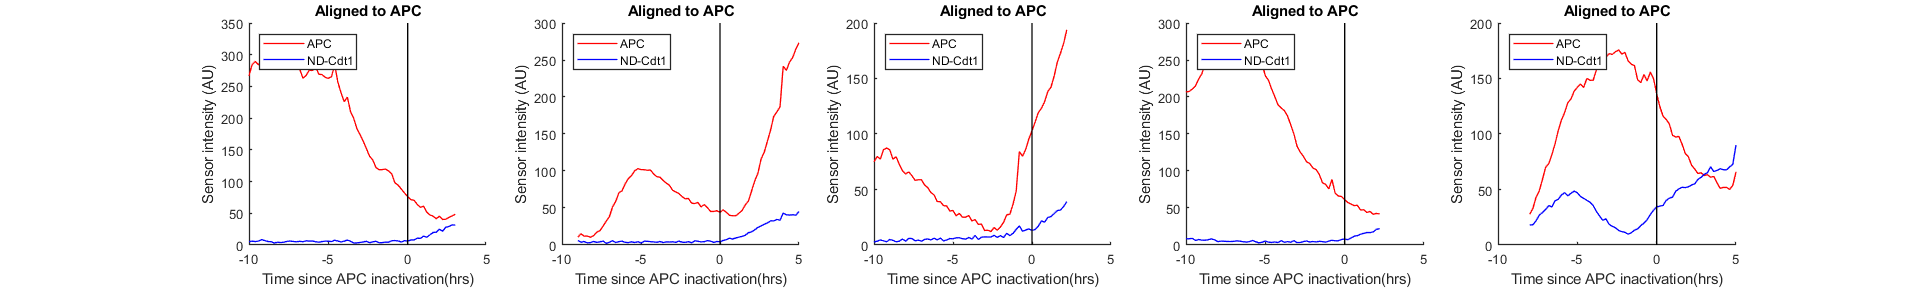

 
cond=5;
num = 5;
figure('pos',[10 10 num*400 300]), hold on
inds = ~isnan(S(cond).POI(:,2)) & max(S(cond).sigNuc,[],2)>100;
cells = randsample(find(inds),num);
for  i = 1:length(cells)
    numcell = cells(i);
    subplot(1,length(cells),i)
    hold on
    times = (xFrames-S(cond).POI(numcell,2))/framesPerHr;
    plot(times , S(cond).sigNuc(numcell,:),'r','linewidth',1)
    plot(times ,S(cond).apcNuc(numcell,:),'b','linewidth',1);

    ylabel('Sensor intensity (AU)');xlabel('Time since APC inactivation(hrs)');
    xlim([-10 5]); 
    %ylim([0 1.2]);
    legend('APC', 'ND-Cdt1','Location','northwest');
    title('Aligned to APC');
    vline(0,'k');
    hold off
%     set(findall(gcf,'-property','FontSize'),'FontSize',16)
    set(gca,'linewidth',1)
    set(findall(gca, 'Type', 'Line'),'LineWidth',1);




end